# projet muttin de team baptiste

版本2，试图取更多的点。步长不变。

## paramètre

f=@(x,y) -15*(x^2+y^2)

f = function_handle with value:
    @(x,y)-15*(x^2+y^2)


Tcontour=28;
h=1;
longueur=51; %longueur de la pièce = son largeur

## matrice coef A

A1=diag(-4*ones(longueur-1,1))+diag(ones(longueur-2,1),-1)+diag(ones(longueur-2,1),1);
A2=diag(ones(1,longueur-1));
A=zeros((longueur-1)^2);
for i=1:50 %
    A(1+(i-1)*50 : 50+(i-1)*50  ,  1+(i-1)*50 : 50+(i-1)*50)=A1;
    
end
for i=1:49 %
    A(51+(i-1)*50 : 100+(i-1)*50  ,  1+(i-1)*50 : 50+(i-1)*50)=A2;
end
for i=1:49 %
    A(1+(i-1)*50 : 50+(i-1)*50  ,  51+(i-1)*50 : 100+(i-1)*50)=A2;
end
A

A =     -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -4     1     0     0     0     0     0     0     0     0     0     0   

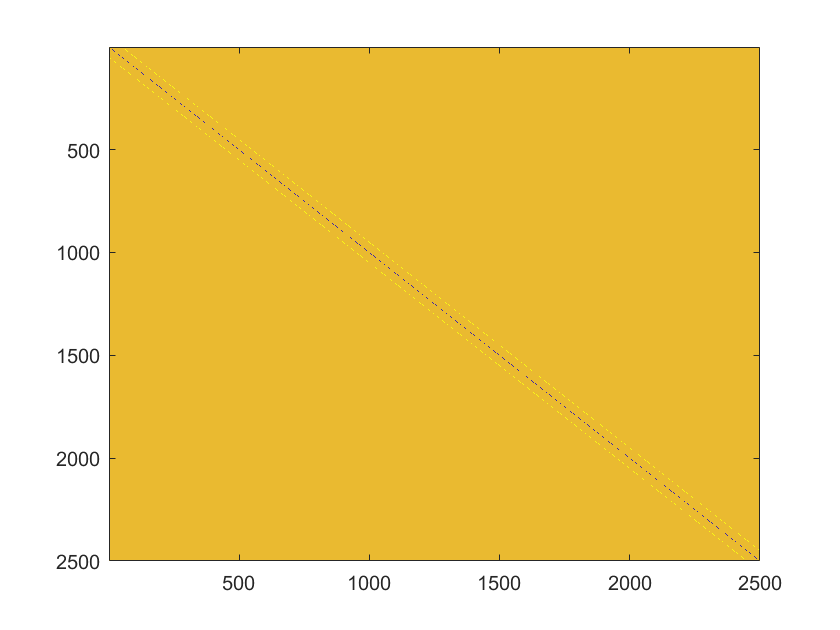

imagesc(A)

## vecteur cste C

temp=zeros(longueur-1);
for i=1:longueur-1
    for j=1:longueur-1
        temp(i,j)=h^2*f(i,j);
    end
end
% 4 pts
temp(1,:)=temp(1,:)-Tcontour;
temp(:,1)=temp(:,1)-Tcontour;
temp(length(temp),:)=temp(length(temp),:)-Tcontour;
temp(:,length(temp))=temp(:,length(temp))-Tcontour;
% % 4 sommet
% temp(1,1)=temp(1,1)-2*Tcontour;
% temp(1,length(temp))=temp(1,length(temp))-2*Tcontour;
% temp(length(temp),1)=temp(length(temp),1)-2*Tcontour;
% temp(length(temp),length(temp))=temp(length(temp),length(temp))-2*Tcontour;
temp

temp =          -86        -103        -178        -283        -418        -583        -778       -1003       -1258       -1543       -1858       -2203       -2578       -2983       -3418       -3883       -4378       -4903       -5458       -6043       -6658       -7303       -7978       -8683       -9418      -10183      -10978      -11803      -12658      -13543      -14458      -15403      -16378      -17383      -18418      -19483      -20578      -21703      -22858      -24043      -25258      -26503      -27778      -29083      -30418      -31783      -33178      -34603      -36058      -37571
        -103        -120        -195        -300        -435        -600        -795       -1020       -1275       -1560       -1875       -2220       -2595       -3000       -3435       -3900       -4395       -4920       -5475       -6060       -6675       -7320       -7995       -8700       -9435      -10200      -10995      -11820      -12675      -13560      -14475      -15420      -1

C=zeros(length(temp)^2,1);
for i=1:length(temp)
    C(1+(i-1)*length(temp):length(temp)+(i-1)*length(temp),1)=temp(i,:);
end
C

C =          -86
        -103
        -178
        -283
        -418
        -583
        -778
       -1003
       -1258
       -1543


## vecteur Tvec

Tvec=A\C

Tvec = 	1.0e+06 *

    0.0109
    0.0218
    0.0326
    0.0435
    0.0543
    0.0651
    0.0759
    0.0867
    0.0974
    0.1081


## matrice final Z

Z=zeros(length(temp)+2)

Z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for i=2:length(Z)-1
    Z(i, 2:length(Z)-1)=Tvec(1+50*(i-2):50+50*(i-2));
end

Z(1,:)=Tcontour;
Z(length(Z),:)=Tcontour;
Z(:,1)=Tcontour;
Z(:,length(Z))=Tcontour;
Z

Z = 	1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0109    0.0218    0.0326    0.0435    0.0543    0.0651    0.0759    0.0867    0.0974    0.1081    0.1188    0.1294    0.1400    0.1505    0.1609    0.1713    0.1815    0.1917    0.2016    0.2115    0.2211    0.2305    0.2396    0.2485    0.2571    0.2652    0.2730    0.2803    0.2871    0.2933    0.2989    0.3037    0.3077    0.3109    0.3130    0.3140    0.3138    0.3123    0.3091    0.3043    0.2976    0.2886    0.2772    0.2629    0.2452    0.2236    0.1972   

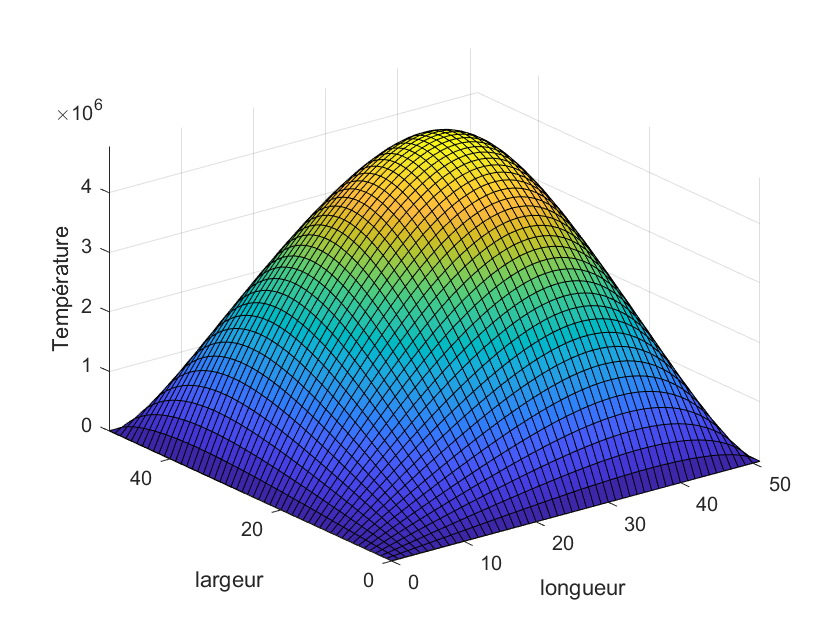

figure(1)
[xq,yq] = meshgrid(0:longueur, 0:longueur);
surfc(xq,yq,Z)
xlabel('longueur')
ylabel('largeur')
zlabel('Température')

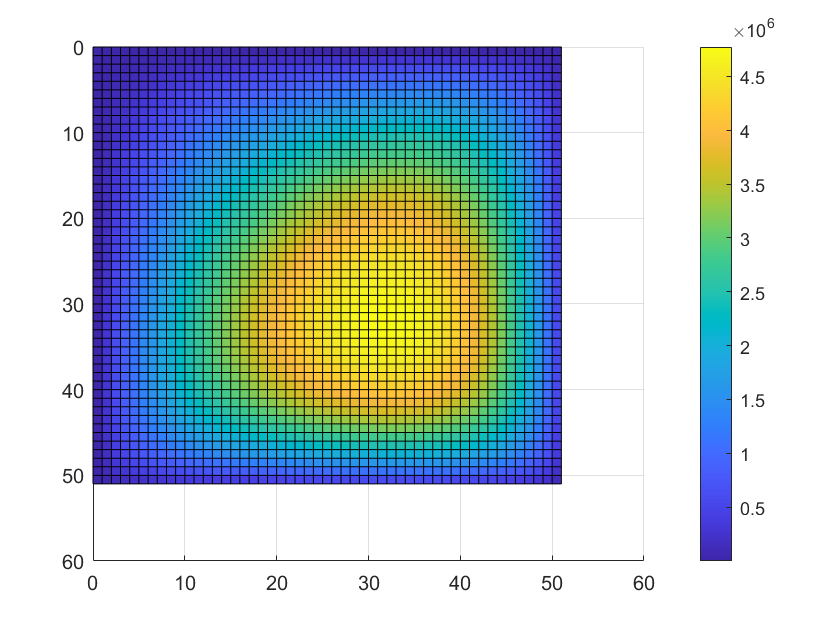


figure(2)
surf(xq,yq,Z)
view([90,90])
colorbar

## this part is no longer necessary


% figure(3)
% nbr_pts=5 % nbr de pts entre deux pts originaux
% accuracy=1/nbr_pts;
% [xqq,yqq] = meshgrid(0:accuracy:longueur, 0:accuracy:longueur); %précision d'interpolation
% vq = griddata(xq,yq,Z,xqq,yqq,'cubic')
% surf(xqq,yqq,vq)
